robot = 10;
tag = 2;

t0 = 1; tf = nPassi; t = t0:tf;

var_x = squeeze(ekfs(robot).varsStoria(1, tag, t))';
var_y = squeeze(ekfs(robot).varsStoria(2, tag, t))';
sigma_x = sqrt(var_x); sigma_y = sqrt(var_y); idx = t;

grad_sigma_x = diff(sigma_x);
grad_sigma_x = [grad_sigma_x, grad_sigma_x(end)];
grad_sigma_y = diff(sigma_y);
grad_sigma_y = [grad_sigma_y, grad_sigma_y(end)];

% Salvataggio dei dati prima del filtro per il plot
grad_sigma_x_orig = grad_sigma_x;
grad_sigma_y_orig = grad_sigma_y;

% Filtro FIR per grad_sigma_x e grad_sigma_y
filtro_finestra = 6; % Lunghezza finestra del filtro
kernel = ones(1, filtro_finestra) / filtro_finestra; % Kernel media mobile

% Applicazione del filtro (manuale)
grad_sigma_x_filtrato = zeros(size(grad_sigma_x));
grad_sigma_y_filtrato = zeros(size(grad_sigma_y));

for i = 1:length(grad_sigma_x)
    for j = 1:filtro_finestra
        if i - j + 1 > 0
            grad_sigma_x_filtrato(i) = grad_sigma_x_filtrato(i) + kernel(j) * grad_sigma_x(i - j + 1);
            grad_sigma_y_filtrato(i) = grad_sigma_y_filtrato(i) + kernel(j) * grad_sigma_y(i - j + 1);
        end
    end
end

% Sostituisci grad_sigma_x e grad_sigma_y con i valori filtrati
grad_sigma_x = grad_sigma_x_filtrato;
grad_sigma_y = grad_sigma_y_filtrato;

% Rimozione valori con grad_sigma_x == 0
cond = (grad_sigma_x == 0);
grad_sigma_x(cond) = []; grad_sigma_y(cond) = []; idx(cond) = [];
grad_sigma_x = grad_sigma_x(10:end);
grad_sigma_y = grad_sigma_y(10:end);
idx = idx(10:end);

% Determinazione dei passi con variazioni decrescenti
diff_thr = 0.0;
decreasing = (grad_sigma_x < diff_thr) & (grad_sigma_y < diff_thr);

threshold = 10; % Numero minimo di passi consecutivi
start_step = -1; % Inizializzazione
for i = threshold:length(decreasing)
    if all(decreasing(i-threshold+1:i))
        start_step = i;
        break;
    end
end

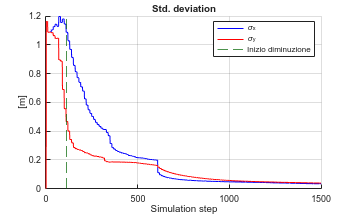

% Plot dei dati
figure;
hold on;
plot(t, sigma_x, 'b', 'DisplayName', '\sigma_x');
plot(t, sigma_y, 'r', 'DisplayName', '\sigma_y');
if start_step > 0
    xline(idx(start_step), '--',  'Color', '#006400', 'DisplayName', 'Inizio diminuzione');
end
xlabel('Simulation step');
ylabel('[m]');
title('Std. deviation');
legend;
grid on;

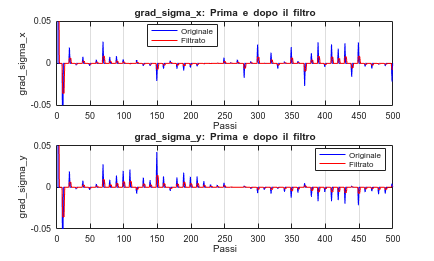

% Plot del confronto
figure;
subplot(2, 1, 1);
plot(idx, grad_sigma_x_orig, 'b-', 'DisplayName', 'Originale');
hold on;
plot(idx, grad_sigma_x, 'r-', 'DisplayName', 'Filtrato');
xlabel('Passi');
ylabel('grad\_sigma\_x');
legend('Location', 'Best');
title('grad\_sigma\_x: Prima e dopo il filtro');
grid on;
xlim([0 500]);
ylim([-0.05 0.05]);

subplot(2, 1, 2);
plot(idx, grad_sigma_y_orig, 'b-', 'DisplayName', 'Originale');
hold on;
plot(idx, grad_sigma_y, 'r-', 'DisplayName', 'Filtrato');
xlabel('Passi');
ylabel('grad\_sigma\_y');
legend('Location', 'Best');
title('grad\_sigma\_y: Prima e dopo il filtro');
grid on;
xlim([0 500]);
ylim([-0.05 0.05]);

robot = 7;
tag = 3;

t0 = 1; tf = nPassi; t = t0:tf;
var_x = squeeze(ekfs(robot).varsStoria(1, tag, t))';
var_y = squeeze(ekfs(robot).varsStoria(2, tag, t))';
sigma_x = sqrt(var_x); sigma_y = sqrt(var_y); idx = t;

grad_sigma_x = diff(sigma_x);
grad_sigma_x = [grad_sigma_x, grad_sigma_x(end)];
grad_sigma_y = diff(sigma_y);
grad_sigma_y = [grad_sigma_y, grad_sigma_y(end)];

cond = (grad_sigma_x == 0);
grad_sigma_x(cond) = []; grad_sigma_y(cond) = []; idx(cond) = [];
grad_sigma_x = grad_sigma_x(10:end);
grad_sigma_y = grad_sigma_y(10:end);
idx = idx(10:end);

diff_thr = 0.01;
decreasing_x = grad_sigma_x < diff_thr; 
decreasing_y = grad_sigma_y < diff_thr;
cond_start_pruning = [false, false];

threshold = 10; % Numero minimo di passi consecutivi
start_step = -1; % Inizializzazione
for i = 1:(length(decreasing_x) - threshold + 1)
    if all(decreasing_x(i:i+threshold-1))
        cond_start_pruning(1) = true;
    
    end
    if all(decreasing_y(i:i+threshold-1))
        cond_start_pruning(2) = true;
    end
    if all(cond_start_pruning)
        start_step = i;
        break;
    end
end

% Plot dei dati
figure;
hold on;
plot(t, sigma_x, 'b', 'DisplayName', '\sigma_x');
plot(t, sigma_y, 'r', 'DisplayName', '\sigma_y');
if start_step > 0
    xline(idx(start_step), '--',  'Color', '#006400', 'DisplayName', 'Inizio diminuzione');
end
xlabel('Simulation step');
ylabel('[m]');
title('Std. deviation');
legend;
grid on;


% Visualizzazione dei risultati
if start_step > 0
    fprintf('Step %d\n', idx(start_step));
else
    fprintf('NO.\n');
end

data = posTagRobot;

% Numero di robot
num_robots = size(data, 3);

% Colori diversi per ogni robot
colors = lines(num_robots); % Usa la funzione "lines" per colori distinti

% Calcolo della media e varianza sui robot
mean_pos = mean(data, 3); % Media sui robot (terza dimensione)
sigma_pos = sqrt(var(data, 0, 3)); % Varianza sui robot (terza dimensione)


figure;
hold on;

for robot = 1:num_robots
    % Estrai le coordinate (x, y) per il robot corrente
    x = data(1, :, robot);
    y = data(2, :, robot);
    
    % Plot delle coordinate dei tag
    scatter(x, y, 50, 'MarkerFaceColor', colors(robot, :), ...
            'MarkerEdgeColor', 'k', 'DisplayName', sprintf('Robot %d', robot));
end

% Plot della media
scatter(mean_pos(1, :), mean_pos(2, :), 150, 'k', 'square', 'filled', ...
        'DisplayName', 'Media (sui robot)');

% Visualizza la varianza come testo accanto alla media
for i = 1:size(mean_pos, 2)
    text(mean_pos(1, i), mean_pos(2, i), ...
        sprintf('\\sigma_x=%.2f, \\sigma_y=%.2f', ...
        sigma_pos(1, i), sigma_pos(2, i)), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Impostazioni grafiche
xlabel('x');
ylabel('y');
title('Coordinate dei tag per ogni robot con media e varianza');
legend('Location', 'best');
grid on;
hold off;
axis equal;
